## Parametros

El eje fijo se deja en:

punto_fijo = [0; 0];

El centro del trebol estará ubicado en (se escogió arbitrariamente):

centro_trebol = [25; 25];

 Con esto, necesitamos que los eslabones en máxima estensión midan al menos:

lado_trebol_max = 15*1.33;
diagonal_max = hypot(lado_trebol_max, lado_trebol_max);
radio_punto_max = hypot(centro_trebol(1), centro_trebol(2)) + diagonal_max/2;

Se escogen como primera aproximación para la longitud de los eslabones:

largo_eslabon_1 = 30;
largo_eslabon_2 = 20;

El punto máximo al que llegarán estos eslabones es:

radio_alcance_max = largo_eslabon_1+largo_eslabon_2;

Con esto, es posible llegar a todos los puntos de la trayectoria con las longitudes escogidas para los eslabones. Y se deja una tolerancia de [cm]:

radio_tolerancia = radio_alcance_max - radio_punto_max;

Se fijan los valores de a y b para que el trebol mida 15cm de lado y esté sin rotar (esto se usa más adelante, en el modelo del trebol):

a_min = 1.332;
b_no_rot = 4.71;

Para ajustar la escala y rotación del trebol:

escala = 1; % default = 1
rotacion = 0; % en radianes
a = a_min * escala;
b = b_no_rot + rotacion;

## Puntas de los eslabones a partir de angulos

syms theta_1;
syms theta_2;

La ubicación de las puntas de los eslabones estará dada por las siguientes expresiones, en donde B es la herramienta de trabajo:

a_x(theta_1) = punto_fijo(1)+largo_eslabon_1*cos(theta_1);
a_y(theta_1) = punto_fijo(2)+largo_eslabon_1*sin(theta_1);
b_x(theta_1, theta_2) = a_x+largo_eslabon_2*cos(theta_1+theta_2);
b_y(theta_1, theta_2) = a_y+largo_eslabon_2*sin(theta_1+theta_2);

## Angulos a partir de posición de B

theta_1_fn_a_x = finverse(a_x); % en la función resultante theta_1 en realidad es a_x
theta_1_fn_a_y = finverse(a_y); % en la función resultante theta_1 en realidad es a_y
theta_2_fn_b_x = finverse(b_x, theta_2); % en la función resultante theta_2 en realidad es b_x
theta_2_fn_b_y = finverse(b_y, theta_2); % en la función resultante theta_2 en realidad es b_y

### Encontrar ángulos a partir de la posición de A y B

a_x_d = 0;
a_y_d = 30;
b_x_d = 20;
b_y_d = 30;

% TODO: Convertir esto en una funcion, angulos teniendo la pos. de A y B.
theta_1_x = theta_1_fn_a_x(a_x_d);
theta_1_y = theta_1_fn_a_y(a_y_d);
theta_2_x = theta_2_fn_b_x(theta_1_fn_a_x(a_x_d), b_x_d);
theta_2_y = theta_2_fn_b_y(theta_1_fn_a_y(a_y_d), b_y_d);

theta_1_desde_a_b = 0;
theta_2_desde_a_b = 0;
if theta_1_x == theta_1_y
    theta_1_desde_a_b = theta_1_x;
end
if theta_2_x == theta_2_y
    theta_2_desde_a_b = theta_2_x;
end
% La funcion iria hasta aca

theta_1_desde_a_b

$$theta\_1\_desde\_a\_b = \frac{\pi }{2}$$

theta_2_desde_a_b

$$theta\_2\_desde\_a\_b = -\frac{\pi }{2}$$

A = [a_x(theta_1_desde_a_b); a_y(theta_1_desde_a_b)];
B = [b_x(theta_1_desde_a_b, theta_2_desde_a_b); b_y(theta_1_desde_a_b, theta_2_desde_a_b)];

### Gráfica

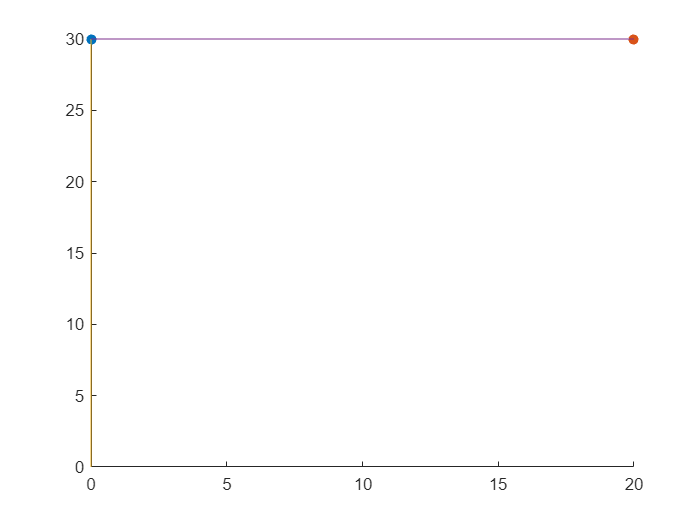

scatter(A(1), A(2), 'filled');
hold on;
scatter(B(1), B(2), 'filled');
plot([punto_fijo(1) A(1)], [punto_fijo(2) A(2)])
plot([A(1) B(1)], [A(2) B(2)])
hold off;

## Cartesian-Space trajectory planning

Usaremos interpolation-based Cartesian-space planning.

### Definir la trayectoria

syms theta_trebol;
trebol_x(theta_trebol) = (a*(sin(4*theta_trebol+b)+6)).*cos(theta_trebol)+centro_trebol(1);
trebol_y(theta_trebol) = (a*(sin(4*theta_trebol+b)+6)).*sin(theta_trebol)+centro_trebol(2);

### Discretización de la trayectoria

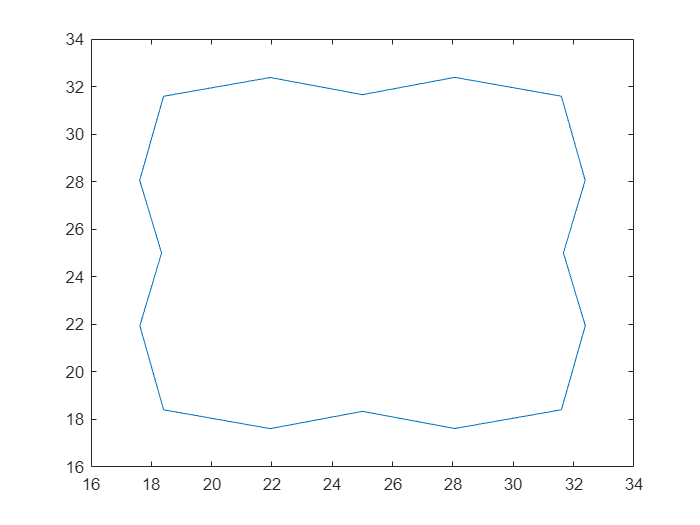

intervalo_theta_trebol = pi/8;
theta_trebol_discreto = 0:intervalo_theta_trebol:2*pi;
trebol_discretizado_x = trebol_x(theta_trebol_discreto);
trebol_discretizado_y = trebol_y(theta_trebol_discreto);
plot(trebol_discretizado_x, trebol_discretizado_y);

### Encontrar ángulos a partir de la posición de B

% TODO: Convertir esto en una funcion, angulos solo teniendo la pos. de B
% (tomar cualquier pos. de A.)
% una forma de hacerlo por fueza bruta es probar todos los valores de
% theta_1 y de theta_2. Esto es MUY ineficiente.
% una mejora sobre esto sería ubicar B y probar todos los valores de
% theta_1 hasta que se encuentre uno en el que la pos. de B sea posible.

theta_1_desde_b = 0/0; % que explote si no encuentra valor
theta_2_desde_b = 0/0;
for theta_1_brute_force = 0:pi/512:2*pi
    theta_2_x_desde_b = theta_2_fn_b_x(theta_1_brute_force, trebol_discretizado_x(1));
    theta_2_y_desde_b = theta_2_fn_b_y(theta_1_brute_force, trebol_discretizado_y(1));
    if (double(theta_2_x_desde_b) - 0.01 <= double(theta_2_y_desde_b)) && (double(theta_2_y_desde_b) <= double(theta_2_x_desde_b) + 0.01) % precision de menos de un grado
        theta_1_desde_b = theta_1_brute_force;
        theta_2_desde_b = theta_2_x_desde_b;
       break
    end
end
% La funcion iria hasta aca
theta_1_desde_b

theta_1_desde_b = 0.1718

theta_2_desde_b

$$theta\_2\_desde\_b = \mathrm{acos}\left(\frac{333\,\sin\left(\frac{471}{100}\right)}{5000}-\frac{3\,\cos\left(\frac{7\,\pi }{128}\right)}{2}+\frac{1031}{625}\right)-\frac{7\,\pi }{128}$$

### Gráfica

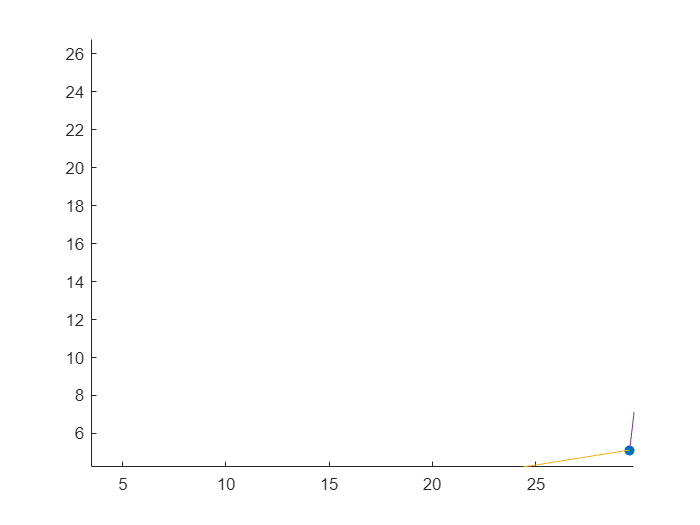

a_desde_b = [a_x(theta_1_desde_b); a_y(theta_1_desde_b)];
b_desde_b = [b_x(theta_1_desde_b, theta_2_desde_b); b_y(theta_1_desde_b, theta_2_desde_b)];

scatter(a_desde_b(1), a_desde_b(2), 'filled');
hold on;
scatter(b_desde_b(1), b_desde_b(2), 'filled');
plot([punto_fijo(1) a_desde_b(1)], [punto_fijo(2) a_desde_b(2)])
plot([a_desde_b(1) b_desde_b(1)], [a_desde_b(2) b_desde_b(2)])
hold off;

double(trebol_discretizado_x(1))

ans = 31.6600

double(trebol_discretizado_y(1))

ans = 25